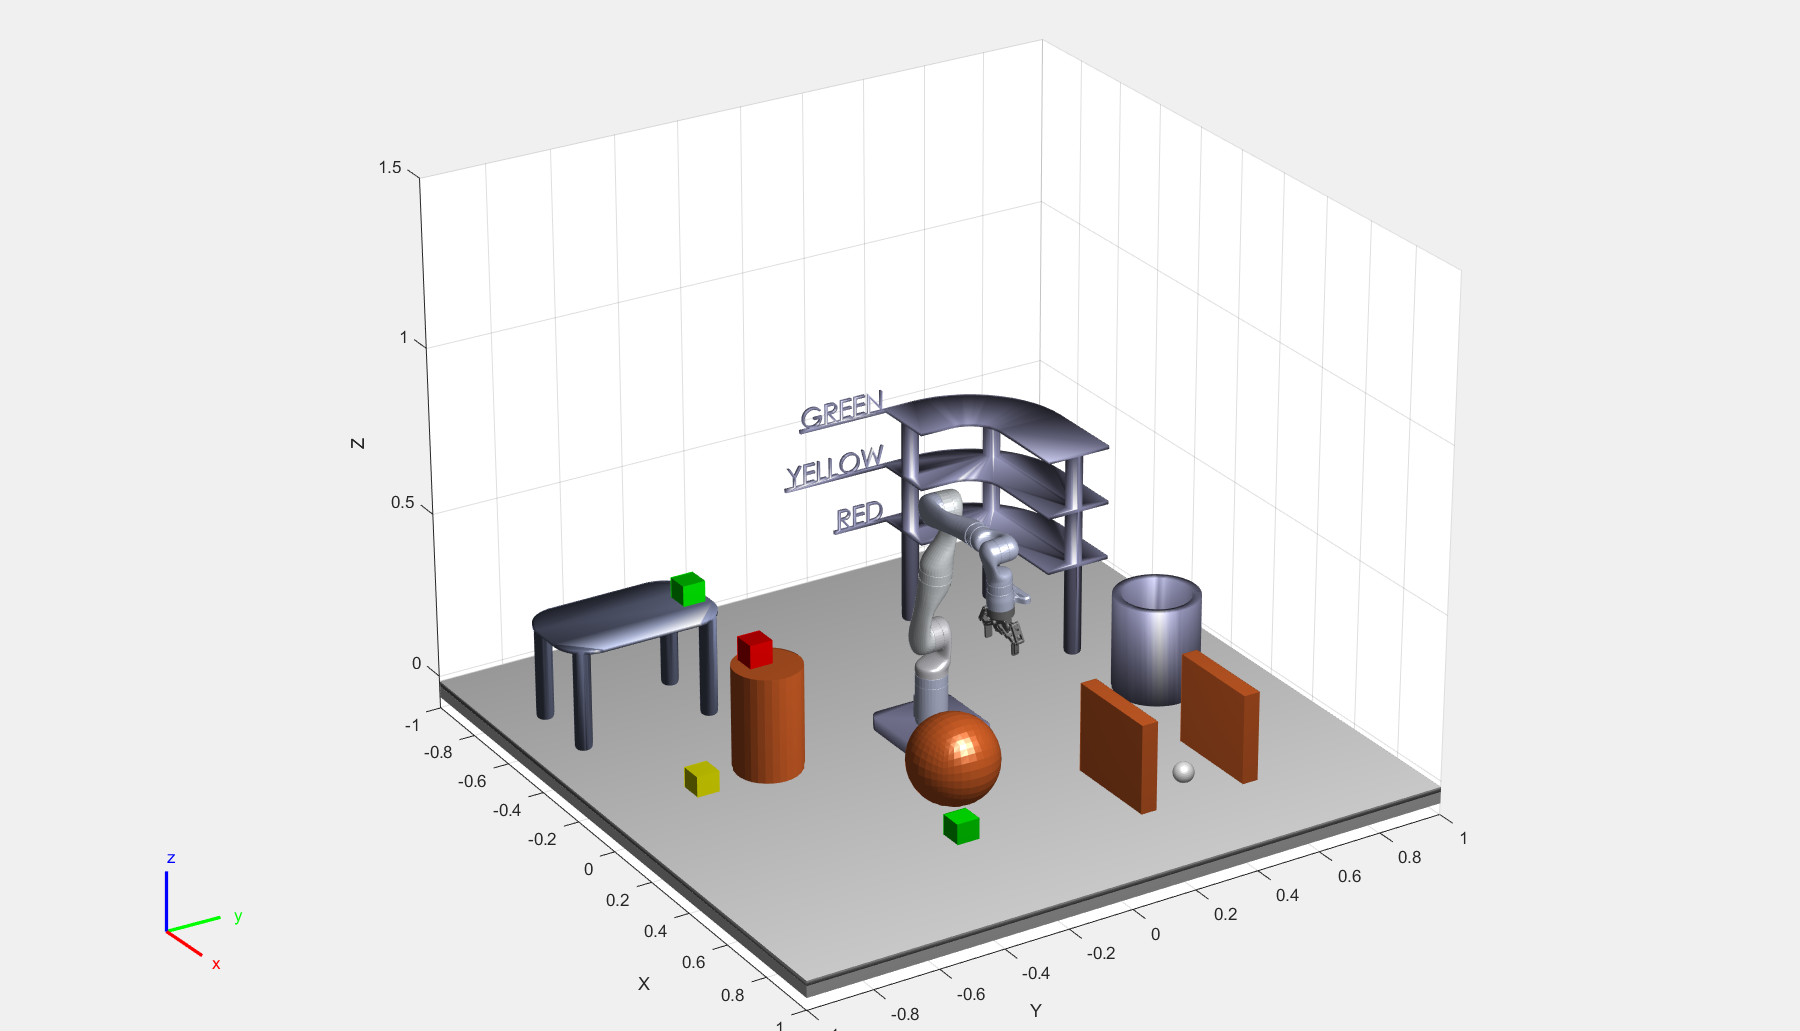



load('KINOVAGen3GripperColl.mat'); 

currentRobotJConfig = homeConfiguration(robot);
coordinator = CoordinatorPickPlace(robot,currentRobotJConfig, "gripper");

coordinator.HomeRobotTaskConfig = trvec2tform([0.4, 0, 0.5])*axang2tform([0 -1 0 pi]);
coordinator.PlacingPose{1} = trvec2tform([[-0.31 0.57 0.3]])*axang2tform([1 0 0 -pi/2]);
coordinator.PlacingPose{2} = trvec2tform([[-0.31 0.57 0.47]])*axang2tform([1 0 0 -pi/2]);
coordinator.PlacingPose{3} = trvec2tform([[-0.27 0.57 0.64]])*axang2tform([1 0 0 -pi/2]);
coordinator.PlacingPose{4} = trvec2tform([[0.03 0.7 0.2]])*axang2tform([0 -1 0 pi]);

coordinator.FlowChart = FlowChartPickPlace('coordinator', coordinator); 

coordinator.FlowChart.startPickPlace;     